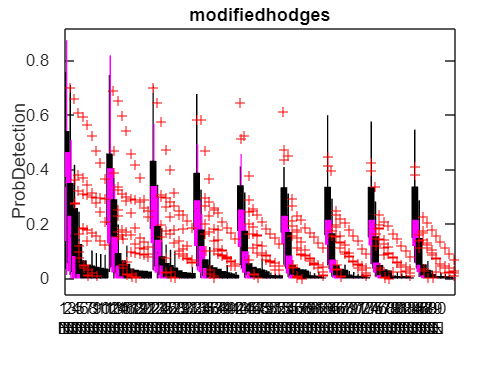

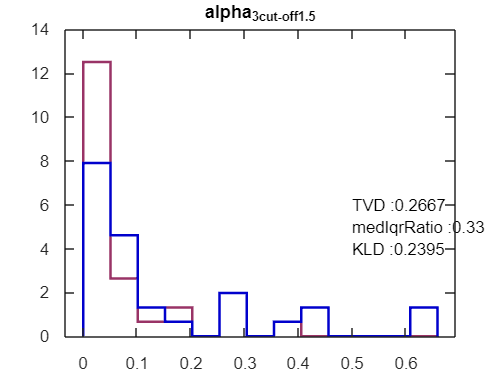

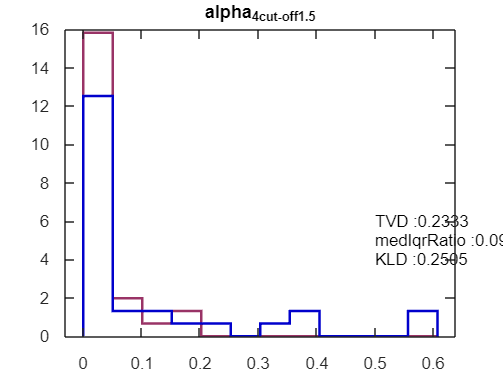

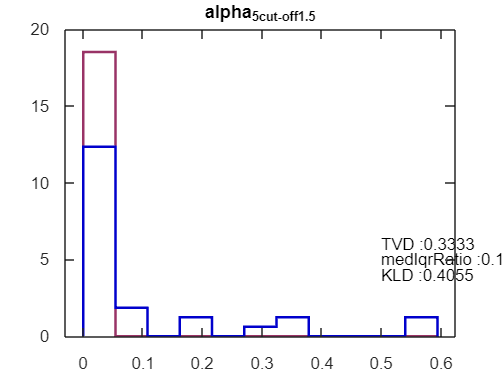

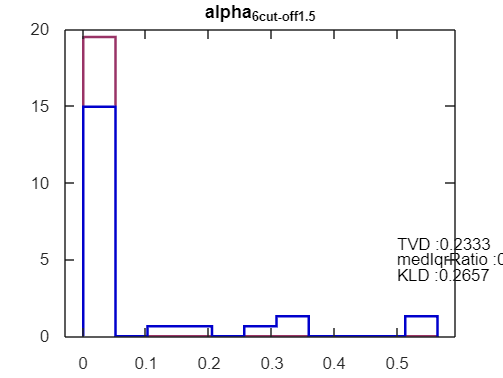

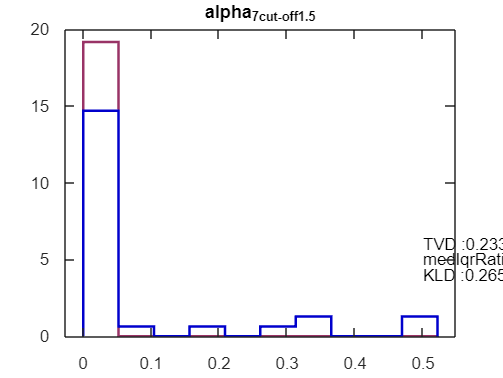

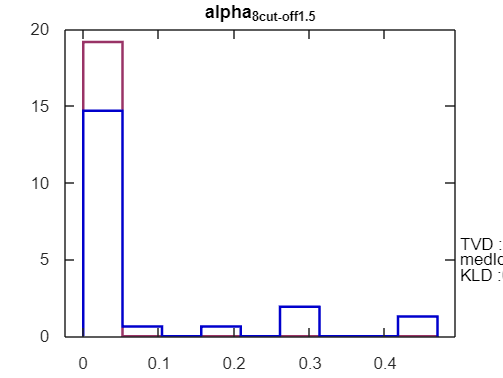

clc
clear all
close all

addpath 'E:\EMG_detectors\library'
Detectors = ["modifiedhodges"];
%%  Get the parameters
    mode = "Train";
    method = "";
    type = "";
    SNR = [];
   paramfuncname = strcat(Detectors(1), '_param');
   paramfunc =  str2func(paramfuncname);
   params = paramfunc(mode,type,SNR,Detectors(1),method);
   combo = 1:numel(params.combo);
   Params = string(combo);
    cutoff = params.fc;

NoTrialPatient = [30 69	95	77	89	90	77	90	95	25	90	61	85	61	55	14	62	90	85	71	53	75	95	80	73	2	27	82	55];

paramcombo = repmat(Params,1,2);
costfactors = [repmat({'E'},1,length(Params)),repmat({'N'},1,length(Params))];
MaxSepAllcombo = load('E:\EMG_detectors\detectors_review_paper\Probdetection\alphamodifiedhodgesPdALLcombo.mat');
for k = 1:length(NoTrialPatient)
    PmoveEMG = MaxSepAllcombo.H1(sum(NoTrialPatient(1:k-1))+1:sum(NoTrialPatient(1:k)),:); %MaxSepAllcombo.MaxSepAllcombo(:,1:2:end);
    PmoveNoise = MaxSepAllcombo.H0(sum(NoTrialPatient(1:k-1))+1:sum(NoTrialPatient(1:k)),:)  ;%MaxSepAllcombo.MaxSepAllcombo(:,2:2:end);
    % %% Plot boxplot of Pd
    figure(k)
    BoxplotData = [PmoveEMG PmoveNoise];
    boxplot(BoxplotData,{paramcombo,costfactors},'colors',repmat('km',1,2),'factorgap',[7 1],'labelverbosity','minor','BoxStyle','filled');
    ylabel('ProbDetection')
    title(Detectors(1))  


% % Include only the trials for which there is some EMG activity than noise 
%  Activetrials = PmoveEMG > PmoveNoise;
 fig1 =1;
 Zscore = [];
 grp = [];
 n=1;
%% plot the probability distribution of null hypothesis H0;
for i=1:length(combo)
    n=n+1;
    % index = find(Activetrials(:,i) == 1);
    Pmovenoise_Log = log(PmoveNoise(:,i));
    Pmovenoise_Log = Pmovenoise_Log(Pmovenoise_Log ~= 0);
    Pmoveemg_Log = log(PmoveEMG(:,i));
    Pmoveemg_Log =  Pmoveemg_Log( Pmoveemg_Log ~= 0);    
    meanH0 = mean(Pmovenoise_Log(isfinite(Pmovenoise_Log)));
    stdH0 = std(Pmovenoise_Log(isfinite(Pmovenoise_Log)));
    zH0 = (Pmovenoise_Log - meanH0)./stdH0;
    zH1 = (Pmoveemg_Log - meanH0)./stdH0;
    
    %% Cummulate all zscore for each combination in a array to plot boxplot
    zH1 = zH1(isfinite(zH1));
    grp = [grp; (i)*ones(size(zH1))];
   
    Zscore = [Zscore; zH1];     
    medianZH1 = median(zH1,'omitnan');
    rangeZH1 = iqr(zH1);   
    ratiomeas(i) = medianZH1/rangeZH1;
    
    %% To ensure number of bins and binwidth is same'BinWidth',0.05
    % Define the desired bin width and calculate the number of bins.
    bin_width = 0.05;  % Adjust the bin width as needed.
    num_bins = (max(max(PmoveNoise(:,i), PmoveEMG(:,i))) - min(min(PmoveNoise(:,i), PmoveEMG(:,i)))) / bin_width;

    % Calculate the bin edges for both histograms.
    bin_edges = linspace(min(min(PmoveNoise(:,i), PmoveEMG(:,i))), max(max(PmoveNoise(:,i), PmoveEMG(:,i))), num_bins + 1);
    %%
    % fig1;
%     fig = figure(fig1);
%     fig.Position = [1 1 1280 647.3333];
% 
%     ind = mod(i,10);
%     if ind == 0
%         disp('inside loop')
%         ind = 10;
%         fig1 = fig1 + 1;
%     end
    % subplot(2,5,ind) 
    fig = figure;
     h_H0 = histogram(PmoveNoise(:,i),'BinEdges',bin_edges,'Normalization','pdf','Displaystyle','stairs','EdgeColor',[0.6 0.2 0.4],'LineWidth',1.5);
     hold on
%     xline(mean(zH0(isfinite(zH0))),'k--')
     h_H1 = histogram(PmoveEMG(:,i),'BinEdges',bin_edges,'Normalization','pdf','Displaystyle','stairs','EdgeColor',[0 0 0.8],'LineWidth',1.5);
     para_ = string(params.combo{i});
     title(strcat('alpha_',para_(1),'_cut-off_',para_(2))) 
    
%% Computing the KL divergence
%     % (a) For only the probabilities    
     kl(i) = kldistance(h_H0.Values,h_H1.Values,h_H0.BinWidth);

%% Computing the median/IQR ratio of the normalise z-scores
    ratiomediqr(i) = median(zH1)/iqr(zH1);

%% Computing the Total variance distance
%     variancemeas = abs(PmoveEMG(:,i) - PmoveNoise(:,i));
%     PH1_TVD = normalisevalue(PmoveEMG(:,i));
%     PH0_TVD = normalisevalue(PmoveNoise(:,i));
    TVD(i) = 0.5 * sum(h_H0.BinWidth*abs(h_H1.Values - h_H0.Values));
    %%
    hold on
    text(0.5,4, strcat('KLD : ' ,num2str(round(kl(i),4))));
    text(0.5,5, strcat('medIqrRatio : ' ,num2str(round(ratiomediqr(i),2))));
    text(0.5,6, strcat('TVD : ' ,num2str(round(TVD(i) ,4))));

%     ylim([0 500])
        % if fig1 > 1 && ind == 5
        %     name = 'Modifiedhodgesmaxsepereation';
        %     export_fig(char(name),'-pdf','-append',figure(fig1-1));
        % end

end

%%
 figure
 boxplot(Zscore,grp)
 ylabel('zscores')
 xlabel('parametercombination')
%  title('AGLR-L')
 
 %% plot the surface plot of the KL close all
 figure
 surf_kl = reshape(kl,[10,9]);
s1 = surface(surf_kl);



colorbar
ylabel('alpha');
xlabel('cut-off freq');
zlabel('Distance')
title('KL- Divergence')

% figure
% surf_TVD = reshape(TVD,[10,9]);
% s2 = surface(surf_TVD);
% % view(3);
% 
% colorbar
% ylabel('alpha');
% xlabel('cut-off freq');
% zlabel('Distance')
% title('TVD')

in = find(kl == max(kl));
bestparam{k} = params.combo{in};
end